addpath('./MatlabFuncs/')

%%NoAP1903
ydata1 =  [0.994351247	0.9916548	0.989389418	0.996206878	0.994587755	0.983118519	0.893697128	0.400989342	0.006447241	0.00148715];
%%NoBlast
ydata2 =  [0.020884656	0.038708919	0.053608692	0.0795322	0.106651625	0.426742328	0.801811791	0.927911111	0.978334618	0.916049206];
%%BothAdded
ydata3 =  [0.028152532	0.050824187	0.055106803	0.078311489	0.12464966	0.216782237	0.052270824	0.020610733	0.004709373	0.000569237];


%Calculate growth rate from confluency data
Y0 = 1/12; K = 1.; t=96;

rdata = revLogest([ydata1; ydata2; ydata3], Y0, K, t)

rdata =     0.0788    0.0747    0.0722    0.0830    0.0793    0.0673    0.0472    0.0208   -0.0275   -0.0428
   -0.0151   -0.0085   -0.0049   -0.0005    0.0028    0.0219    0.0395    0.0516    0.0647    0.0499
   -0.0119   -0.0055   -0.0046   -0.0007    0.0047    0.0116   -0.0052   -0.0152   -0.0308   -0.0528


rpredict = rdata(1, :) + rdata(2, :) - max(max(rdata))

rpredict =    -0.0193   -0.0167   -0.0157   -0.0005   -0.0009    0.0062    0.0037   -0.0106   -0.0458   -0.0760



revY = endLogest([rdata; rpredict], Y0, K, 96)

revY =     0.9938    0.9909    0.9884    0.9959    0.9941    0.9816    0.8851    0.3803    0.0059    0.0014
    0.0192    0.0356    0.0494    0.0734    0.0986    0.4056    0.7876    0.9219    0.9764    0.9091
    0.0259    0.0468    0.0507    0.0723    0.1155    0.2024    0.0481    0.0189    0.0043    0.0005
    0.0129    0.0164    0.0181    0.0734    0.0711    0.1314    0.1061    0.0292    0.0010    0.0001


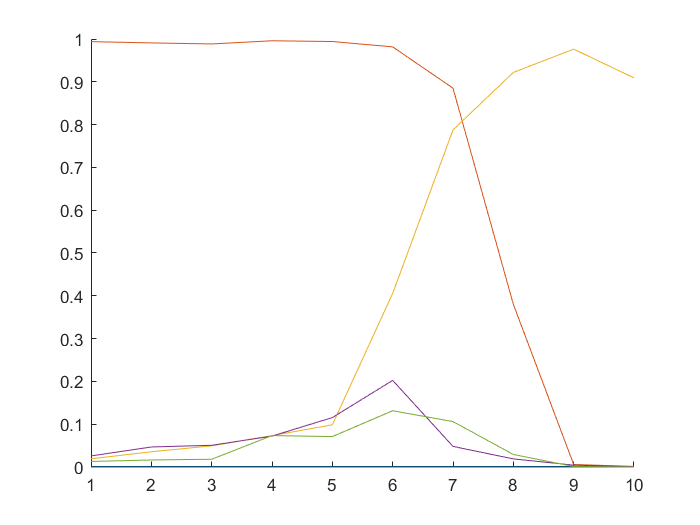


fig = figure(1); clf(fig)
hold on;
plot([1, 10], [0, 0]);
plot(revY');
% plot(rdata(1, :) + rdata(2, :) - max(max(rdata)), 'color', [0, 0, 0]);
hold off;